format short

N = 10;  
p = 0.45;  
q = 0.55; 

% Transition matrix
P = zeros(N+1, N+1);  
P(1,1) = 1;  
P(N+1,N+1) = 1;  

for row = 2:N
    P(row, row-1) = q; 
    P(row, row+1) = p;
end
P;
Q = P(2:N, 2:N); %transient to transient 99 x 99
R = [P(2:N, 1), P(2:N, N+1)]; %transient to absorption 99 x 2
I = eye(size(Q));
F = inv(I-Q);
l = length(F)

l = 9

c = ones(l,1)

c =      1
     1
     1
     1
     1
     1
     1
     1
     1


D = F*c

D =     6.5487
   12.3304
   17.1748
   20.8734
   23.1717
   23.7586
   22.2536
   18.1920
   11.0056


D_full = [0; D; 0];
d_W = D_full(:,1)

d_W =          0
    6.5487
   12.3304
   17.1748
   20.8734
   23.1717
   23.7586
   22.2536
   18.1920
   11.0056


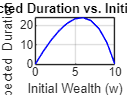


figure;
plot(0:N, d_W, 'b', 'LineWidth', 1);
xlabel('Initial Wealth (w)');
ylabel('Expected Duration (d_W)');
title('Expected Duration vs. Initial Wealth');
grid on;